#  Load, register, segment and neuropil correct 2P data

## Path names

fn_base = '\\duhs-user-nc1.dhe.duke.edu\dusom_glickfeldlab\All_Staff';
lg_fn = fullfile(fn_base, 'home\lindsey');
data_fn = fullfile(lg_fn, 'Data\2P_images');
mworks_fn = fullfile(fn_base, 'Behavior\Data');
fnout = fullfile(lg_fn, 'Analysis\2P\test');

## Specific experiment information

date = '200825';
ImgFolder = '003';
time = '1248';
mouse = 'i1328';
frame_rate = 15.5;
run_str = catRunName(ImgFolder, 1);
datemouse = [date '_' mouse];
datemouserun = [date '_' mouse '_' run_str];

## Load 2P data

Load mworks data (stimulus and behavior information)

fName = fullfile(mworks_fn, ['data-' mouse '-' date '-' time '.mat']);
load(fName);

Load 2P metadata

CD = fullfile(data_fn, mouse, date, ImgFolder);
cd(CD);
imgMatFile = [ImgFolder '_000_000.mat'];
load(imgMatFile);

Load 2P images

totframes = input.counterValues{end}(end); %this is from the mworks structure- finds the last value clocked for frame count
fprintf(['Reading ' num2str(totframes) ' frames \r\n'])
data = sbxread([ImgFolder '_000_000'],0,totframes);

Data is nPMT x nYpix x nXpix x nframes. 

fprintf(['Data is ' num2str(size(data))])

When imaging a single channel, nPMT = 1, so squeeze:

data = squeeze(data);

## Register 2P data

Goal here is to remove X-Y movement artifacts

1. Find a stable target

    a. Plot average of 500 frames throughout stack

nframes = 500; %nframes to average
nskip = 1500; %nframes to skip for each average

nep = floor(size(data,3)./nskip);
[n n2] = subplotn(nep); 
figure('units','normalized','outerposition',[0 0 1 1]);
for i = 1:nep; 
    subplot(n,n2,i); 
    imagesc(mean(data(:,:,1+((i-1)*nskip):nframes+((i-1)*nskip)),3)); 
    title([num2str(1+((i-1)*nskip)) '-' num2str(nframes+((i-1)*nskip))]); 
end


    b. GUI to select target image- choose one that is sharp and close to center of stack

f=gcf;
w = waitforbuttonpress; %click on subplot

w = 0

if w == 0
    axesClicked = gca;
    allAxes = flipud(findobj(f.Children,'Type','axes'));
    numClicked = find(axesClicked==allAxes);
    close all
end
fprintf(['Selected subplot ' num2str(numClicked)])

    c. Create target image

data_avg = mean(data(:,:,1+((numClicked-1)*nskip):nframes+((numClicked-1)*nskip)),3); 

2. stackRegister minimizes the difference of each frame from the target

[out, data_reg] = stackRegister(data,data_avg);

Starting, frame 0
Frame 250 (7.0 fps)
Frame 500 (8.0 fps)
Frame 750 (8.4 fps)
Frame 1000 (8.6 fps)
Frame 1250 (8.6 fps)
Frame 1500 (8.7 fps)
Frame 1750 (8.7 fps)
Frame 2000 (8.8 fps)
Frame 2250 (8.8 fps)
Frame 2500 (8.9 fps)
Frame 2750 (8.9 fps)
Frame 3000 (8.9 fps)
Frame 3250 (8.9 fps)
Frame 3500 (8.9 fps)
Frame 3750 (8.9 fps)
Frame 4000 (8.9 fps)
Frame 4250 (8.9 fps)
Frame 4500 (8.9 fps)
Frame 4750 (8.9 fps)
Frame 5000 (8.9 fps)
Frame 5250 (9.0 fps)
Frame 5500 (9.0 fps)
Frame 5750 (9.0 fps)
Frame 6000 (9.0 fps)
Frame 6250 (9.0 fps)
Frame 6500 (9.0 fps)
Frame 6750 (9.0 fps)
Frame 7000 (9.0 fps)
Frame 7250 (9.0 fps)
Frame 7500 (9.0 fps)
Frame 7750 (9.0 fps)
Frame 8000 (9.0 fps)
Frame 8250 (9.0 fps)
Frame 8500 (9.0 fps)
Frame 8750 (9.0 fps)
Frame 9000 (9.0 fps)
Frame 9250 (9.0 fps)
Frame 9500 (9.0 fps)
Frame 9750 (9.0 fps)
Frame 10000 (9.0 fps)
Frame 10250 (9.0 fps)
Frame 10500 (9.0 fps)
Frame 10750 (9.0 fps)
Frame 11000 (9.0 fps)
Frame 11250 (9.0 fps)
Frame 11500 (9.0 fps)
Frame 11750 

New average image after registration

data_reg_avg = mean(data_reg,3);

Save registration shifts and target, and mworks data

mkdir(fullfile(fnout, datemouse, datemouserun))
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_reg_shifts.mat']), 'data_reg_avg', 'out', 'data_avg')
save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_input.mat']), 'input')

Test registration

    a. Make sure first and last images are sharp and similar. Focus on vasculature and nuclei- not cells since F changes

ind = [1 nep];
for i = 1:length(ind) 
    subplot(2,1,i); 
    ix = ind(i);
    imagesc(mean(data_reg(:,:,1+((ix-1)*nskip):nframes+((ix-1)*nskip)),3)); 
    title([num2str(1+((ix-1)*nskip)) '-' num2str(nframes+((ix-1)*nskip))]); 
end
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_first&last.pdf']), '-dpdf')

    b. Average of all frames should be sharp

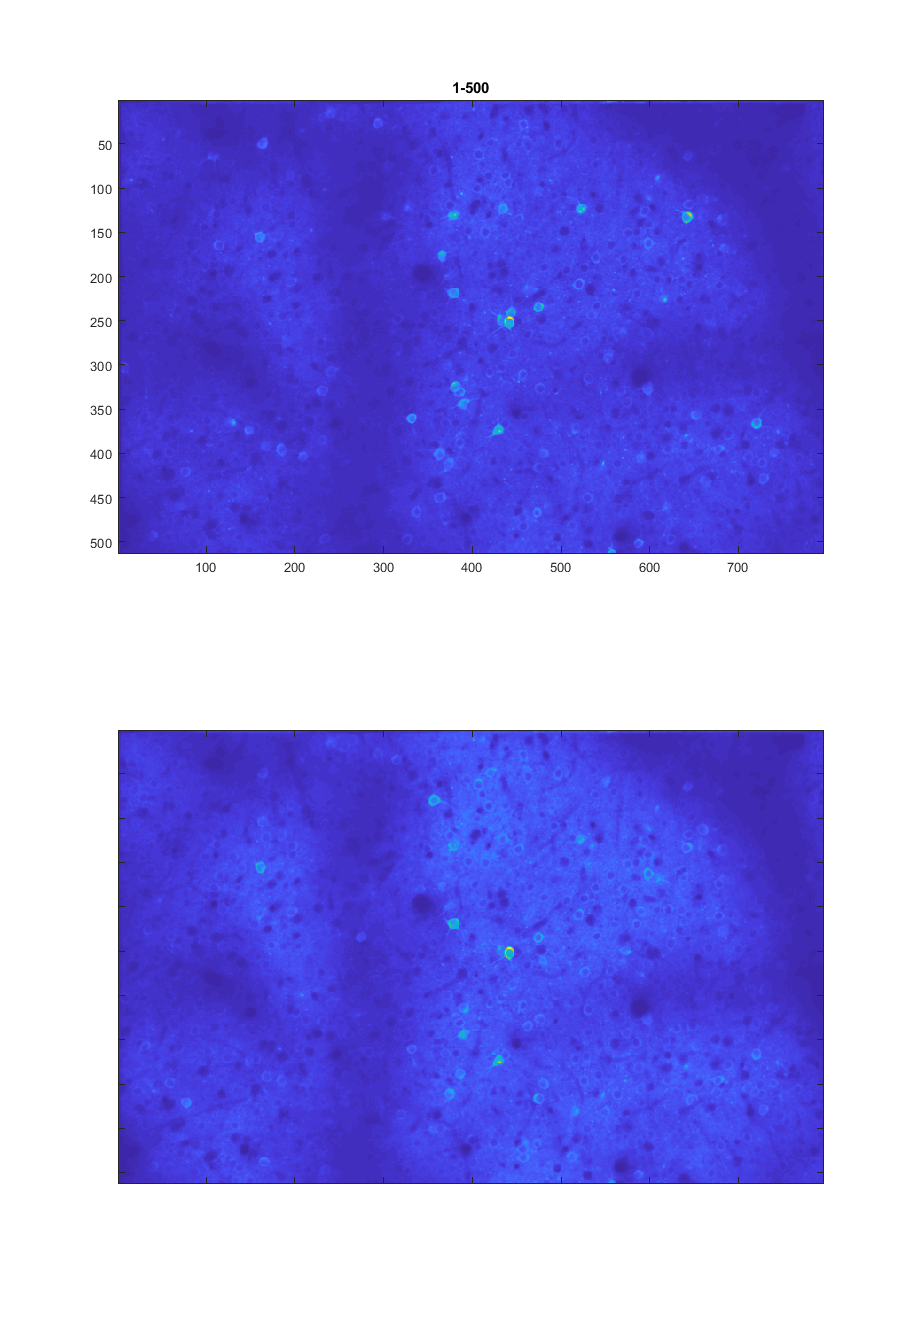

imagesq(data_reg_avg); 
print(fullfile(fnout, datemouse, datemouserun, [datemouserun '_FOV_avg.pdf']), '-dpdf')

clear data

## Segment 2P data

Goal here is to create a cell mask to extract fluorescence timecourses

1. Find activated cells

    a. Reshape data stack to segregate trials 

    First need to know how many frames per trial and how many trials

nOn = input.nScansOn;
nOff = input.nScansOff;
ntrials = size(input.tGratingDirectionDeg,2); %this is a cell array with one value per trial, so length = ntrials
sz = size(data_reg);

        Each trial has nOff frames followed by nOn frames, so can reshape stack so nYpix x nXpix x nFrames/Trial (nOn+nOff) x nTrials

data_tr = reshape(data_reg,[sz(1), sz(2), nOn+nOff, ntrials]);
fprintf(['Size of data_tr is ' num2str(size(data_tr))])

    b. Find baseline F from last half of off period- avoids decay of previous on trial

data_f = mean(data_tr(:,:,nOff/2:nOff,:),3); 

    c. Find dF/F for each trial

data_df = bsxfun(@minus, double(data_tr), data_f); 
data_dfof = bsxfun(@rdivide,data_df, data_f); 
clear data_f data_df data_tr

    d. Find average dF/F for each stimulus condition (this is for an experiment with changing grating direction)

Dir = celleqel2mat_padded(input.tGratingDirectionDeg); %transforms cell array into matrix (1 x ntrials)
Dirs = unique(Dir);
nDirs = length(Dirs);
data_dfof_avg = zeros(sz(1),sz(2),nDirs); %create empty matrix with FOV for each direction: nYpix x nXPix x nDir

nStim = nDirs;
[n n2] = subplotn(nDirs); %function to optimize subplot number/dimensions
for idir = 1:nDirs
    ind = find(Dir == Dirs(idir)); %find all trials with each direction
    data_dfof_avg(:,:,idir) = mean(mean(data_dfof(:,:,nOff+1:nOn+nOff,ind),3),4); %average all On frames and all trials
    subplot(n,n2,idir)
    imagesc(data_dfof_avg(:,:,idir))
end
clear data_dfof

        Filtering data helps make cells more visible for selection

myfilter = fspecial('gaussian',[20 20], 0.5);
data_dfof_avg_all = imfilter(data_dfof_avg,myfilter);
data_dfof_max = max(data_dfof_avg_all,[],3); %finds all active cells by taking max projection

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_stimActFOV.mat']), 'data_dfof_max', 'data_dfof_avg_all', 'nStim')

    2. Create cell masks from active cells

        Concatenate images of max and all directions

data_dfof = cat(3,data_dfof_max, data_dfof_avg_all);

        Set up empty matrices for segmenting cells

mask_data = data_dfof;
mask_exp = zeros(sz(1),sz(2));
mask_all = zeros(sz(1), sz(2));

        a. Click on bright cells in mask to create mask- blue shading should fill bright region of single cell evenly.  

            If cell not filled well, press 'z' or shift+click to remove. Try again by 1) clicking on different spot- brighter spot will make fill smaller- if there are two cells also helps to fill brighter cell first; 2) change threshold- higher thresh will make fill smaller; 3) wait for different image where cell might be more distinct from background

            Press 'return' when done with each image. 

            Next images will have black spots where cells were previously selected- don't let new masks encroach on old cells or will fuse. imCellBuffer helps with this.

for iStim = 1:size(data_dfof,3)    
    mask_data_temp = mask_data(:,:,iStim);
    mask_data_temp(find(mask_exp >= 1)) = 0; %blacks out old cells
    bwout = imCellEditInteractiveLG(mask_data_temp); %selection GUI
    mask_all = mask_all+bwout; %adds new cells to old cells
    mask_exp = imCellBuffer(mask_all,3)+mask_all; %creates buffer around cells to avoid fusing
    close all
end

Added object #1: 150 pix


Added object #2: 154 pix


Added object #3: 71 pix


Added object #4: 156 pix


Added object #5: 451 pix


Undo!  4 cells total now
Added object #5: 147 pix


Added object #6: 161 pix


Added object #7: 132 pix


Added object #8: 161 pix


Added object #9: 157 pix


Added object #10: 117 pix


Added object #11: 176 pix


Added object #12: 187 pix


Added object #13: 148 pix


Added object #14: 145 pix


Added object #15: 152 pix


Added object #16: 157 pix


Added object #17: 125 pix


Added object #18: 136 pix


Added object #19: 623 pix


Undo!  18 cells total now
Added object #19: 146 pix


Added object #20: 189 pix


Added object #21: 163 pix


Added object #22: 150 pix


Added object #23: 162 pix


Added object #24: 149 pix


Added object #25: 136 pix


Added object #26: 169 pix


Added object #27: 162 pix


Added object #28: 150 pix


Added object #29: 167 pix


Added object #30: 155 pix


Added object #31: 109 pix


Added object #32: 161 pix


Added object #33: 131 pix


Added object #34: 130 pix


Added object #35: 126 pix


Added object #36: 120 pix


Added object #37: 162 pix


Added object #38: 86 pix


Added object #39: 185 pix


Added object #40: 204 pix


Added object #41: 98 pix


Added object #42: 156 pix


Added object #43: 838 pix


Undo!  42 cells total now
Added object #43: 151 pix


Added object #44: 156 pix


Added object #45: 120 pix


Added object #46: 132 pix


Added object #47: 406 pix


Undo!  46 cells total now
Added object #47: 141 pix


Added object #48: 140 pix


Added object #49: 102 pix


Added object #50: 131 pix


imCellEditInteractiveLG: done, 50 objects total).


Added object #1: 155 pix


Added object #2: 164 pix


Added object #3: 152 pix


Added object #4: 166 pix


Added object #5: 296 pix


Added object #6: 213 pix


Undo!  5 cells total now


Undo!  4 cells total now
Added object #5: 218 pix


Added object #6: 209 pix


Added object #7: 121 pix


Added object #8: 127 pix


Added object #9: 121 pix


imCellEditInteractiveLG: done, 9 objects total).


Added object #1: 116 pix


Added object #2: 169 pix


Added object #3: 219 pix


Added object #4: 163 pix


Added object #5: 135 pix


imCellEditInteractiveLG: done, 5 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


imCellEditInteractiveLG: done, 0 objects total).


        b. Number independent regions for mask

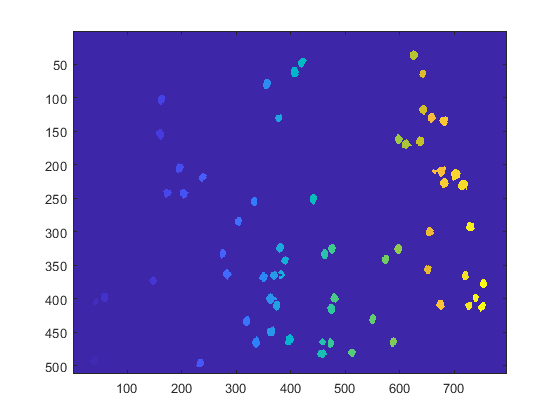

mask_cell = bwlabel(mask_all); %turns logical into numbered cells
figure;
imagesc(mask_cell)

        c. Create neuropil masks (these are regions around each cell without overlap from neighboring cells)

nMaskPix = 5; %thickness of neuropil ring in pixels
nBuffPix = 3; %thickness of buffer between cell and ring
mask_np = imCellNeuropil(mask_cell,nBuffPix,nMaskPix);

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_mask_cell.mat']), 'data_dfof_max', 'mask_cell', 'mask_np')
clear data_dfof data_dfof_avg max_dfof mask_data mask_all mask_2 data_base data_base_dfof data_targ data_targ_dfof data_f data_base2 data_base2_dfof data_dfof_dir_all data_dfof_max data_dfof_targ data_avg data_dfof2_dir data_dfof_dir 

## Neuropil subtraction

Goal is to remove contamination from out-of-focus fluorescence

- Extract cell timecourses

data_tc = stackGetTimeCourses(data_reg, mask_cell); %applies mask to stack to get timecourses

            Timecourses are nFrames x nCells

fprintf(['data_tc is ' num2str(size(data_tc))]) 
nCells = size(data_tc,2);

            Downsampled timecourses for neuropil subtraction- averageing decreases noise

down = 5; %number of frames to average
data_reg_down = stackGroupProject(data_reg,down); %averages every 5 frames in stack  
data_tc_down = stackGetTimeCourses(data_reg_down, mask_cell);    

        2.  Extract neuropil timecourses (full and downsampled)

sz = size(data_reg);
np_tc = zeros(sz(3),nCells);
np_tc_down = zeros(floor(sz(3)./down), nCells);
for i = 1:nCells
     np_tc(:,i) = stackGetTimeCourses(data_reg,mask_np(:,:,i));
     np_tc_down(:,i) = stackGetTimeCourses(data_reg_down,mask_np(:,:,i));
     fprintf(['Cell #' num2str(i) '%s\n']) 
end

Cell #1Cell #2Cell #3Cell #4Cell #5Cell #6Cell #7Cell #8Cell #9Cell #10Cell #11Cell #12Cell #13Cell #14Cell #15Cell #16Cell #17Cell #18Cell #19Cell #20Cell #21Cell #22Cell #23Cell #24Cell #25Cell #26Cell #27Cell #28Cell #29Cell #30Cell #31Cell #32Cell #33Cell #34Cell #35Cell #36Cell #37Cell #38Cell #39Cell #40Cell #41Cell #42Cell #43Cell #44Cell #45Cell #46Cell #47Cell #48Cell #49Cell #50Cell #51Cell #52Cell #53Cell #54Cell #55Cell #56Cell #57Cell #58Cell #59Cell #60Cell #61Cell #62Cell #63Cell #64

        3. Find best neuropil weights by maximizing skew on downsampled subtractions

            Assumes calcium signals are 1) sparse and 2) positive.  Too little subtraction will decrease sparseness and too much will make signals negative. Thus, the best neuropil subtraction should yield the highest skew.

        a. Measure skew for all weights:

ii= 0.01:0.01:1;
x = zeros(length(ii), nCells);
for i = 1:100
    x(i,:) = skewness(data_tc_down-tcRemoveDC(np_tc_down*ii(i)));
end

        b. Find index with highest skew for each cell

[max_skew ind] =  max(x,[],1); 

        c. convert to weight

np_w = 0.01*ind; 

        4. Subtract weighted neuropil response from full timecourses

npSub_tc = data_tc-bsxfun(@times,tcRemoveDC(np_tc),np_w);
clear data_reg data_reg_down

save(fullfile(fnout, datemouse, datemouserun, [datemouserun '_TCs.mat']), 'data_tc', 'np_tc', 'npSub_tc')